## Computer Exercises 1 - EPFL 2024

#### Hugo Penichou

#### Matthieu Scharffe

clc
clear all
close all

## 2.1 Multiplicative uncertainty

%% miscellaneous variables and plotting setup 

Ts = 0.002 ; % sampling time in s 
freqs = (pi/4096:pi/4096:pi) / Ts ; 

opts = nyquistoptions; 
opts.ConfidenceRegionDisplaySpacing = 3;
opts.ShowFullContour = 'off';

%% load data
% Define the list of files
files = {'Data/logs_1.mat', 'Data/logs_3.mat', 'Data/logs_5.mat', ...
         'Data/logs_7.mat', 'Data/logs_9.mat', 'Data/logs_11.mat'};


Let's start by identifying the model for the first set of data

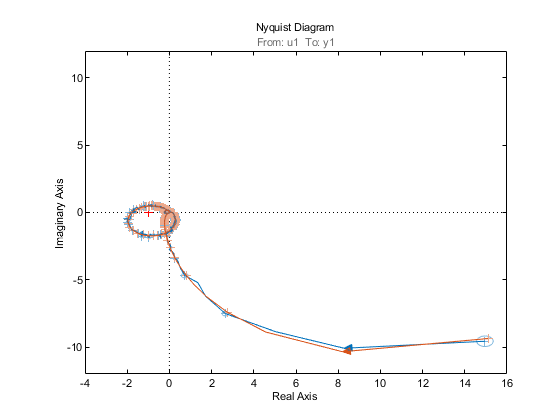

%% load data and identify the model 

% intitialization (identify model with first file)
load( files{1} )
G_current = oe(data , [8, 8, 1] ) ; 
Gf_current = spa(data, 8191, freqs) ; 
G = stack( 1 , G_current ) ; 
Gf = stack( 1 , Gf_current ) ; 

nyquistplot ( Gf , G , freqs , opts , 'sd' , 2.45) ;

The uncertainties of the parametrical model have elliptical shape. It means that the associated covariance matrix is not symmetrical.

Let's do the same thing on all the data

for idx = 2:length(files)
    disp(files{idx});
    load( files{idx} ) ; 
    G_current = oe(data , [8, 8, 1] ) ; 
    Gf_current = spa( data , 8191 , freqs ) ; 
    G = stack( 1 , G , G_current ) ; 
    Gf = stack( 1 , Gf , Gf_current ) ; 
end

Data/logs_3.mat
Data/logs_5.mat
Data/logs_7.mat
Data/logs_9.mat
Data/logs_11.mat


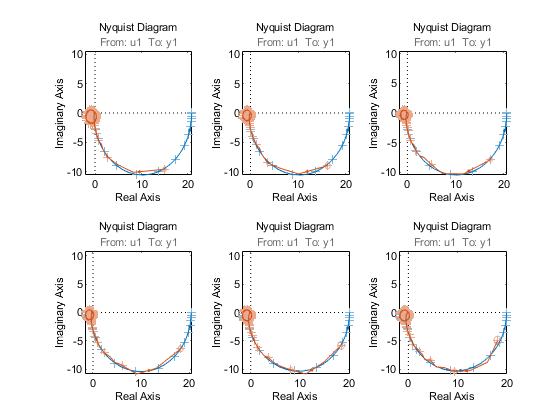


figure(1)

for i = 1:length(G)
    subplot( 2 , 3 , i )
    nyquistplot( G(:,:,i,:) , Gf(:,:,i,:) , opts , 'sd' , 2.45 ) ; 
end

[~, info1] = ucover( G , G(:,:,1,:) , 4 ) ;
W_current = info1.W1 ; 
n_inf_current = norm( W_current , inf ) ; 

W = stack( 1 , W_current ) ; 
n_inf = n_inf_current ; 

for i = 2:length(G)
    [~, info1] = ucover( G , G(:,:,i,:) , 4 ) ;
    W_current = info1.W1 ;  
    n_inf_current = norm( info1.W1opt , inf ) ; 
    W = stack( 1 , W , W_current ) ; 
    n_inf = [n_inf , n_inf_current] ;
end

chosen_one = find( n_inf == min( n_inf ) ) ; 

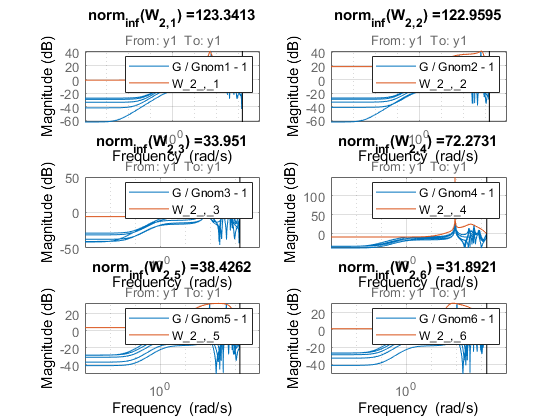

figure(2)
for i = 1:length(G)
    nom_S = strcat( 'G / Gnom' , num2str( i ) , ' - 1' ) ;
    W_S = strcat( 'W_2_,_' , num2str( i ) ) ;
    subplot(3, 2, i)
    G_disp=G;
    G_disp(:,:,i,:)=[];
    bodemag( G_disp / G(:,:,i,:) - 1 , W(:,:,i,:) ) ; grid on ; legend( nom_S , strcat(W_S) ) ; 
    title( strcat( 'norm_{inf}(', W_S , ') = ', num2str( n_inf(i) ) ) )
end

We should pick the model which gives the lowest infinite norm values for the uncertainty filter. This means that we pick the model 11 as the nominal one.

## 2.2  Model-based H∞ control design

### define W1 filter

s=tf('s'); m=0.505; omega_b=8;
W1s=m*(s+omega_b)/(s+1e-5) ;
W1d=c2d(W1s,Ts,'tustin') ;
chosen_one=6;

### compute H_inf controller

Gnom = G( : , : , chosen_one , : ) ;
W2n = W( : , : , chosen_one , : ) ; 
[ K_inf_1 , CL , gamma ] = mixsyn( tf(Gnom) , W1d , [] , W2n ) ;
gamma

gamma = 1.6538

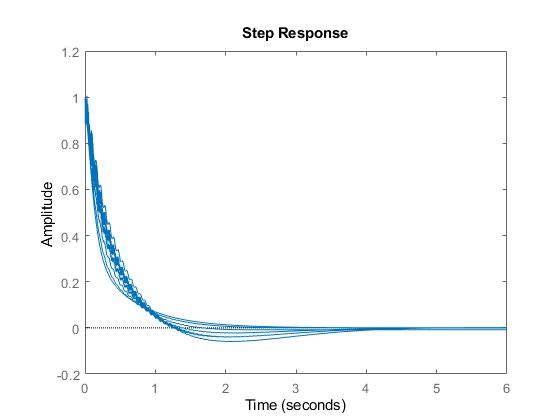

S = feedback( 1, G * K_inf_1 ) ;
T = feedback( G * K_inf_1 , 1 ) ;
U = feedback( K_inf_1 , G ) ;
    
figure(3)
step(S);

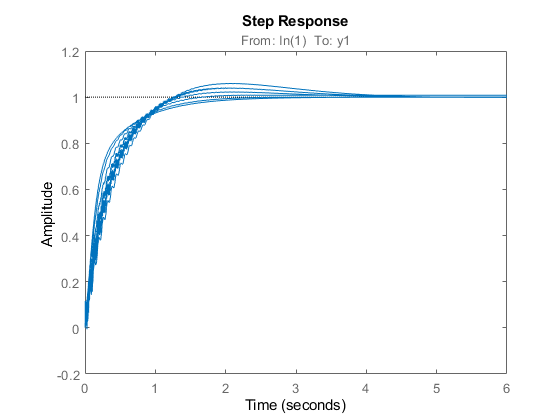

step(T);

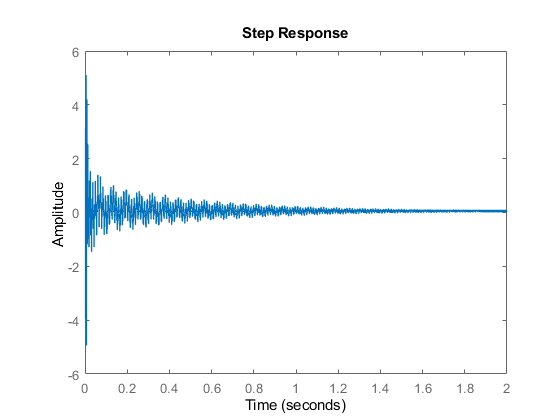

step(U);

disp("fin")

fin


### ADD W3 filter

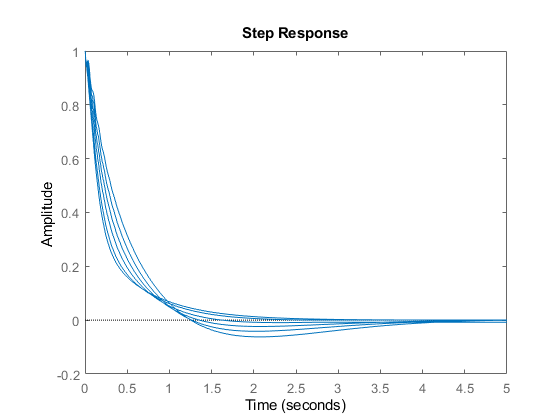


W3=1/1.5;

[K_inf_2,CL,gamma] = mixsyn( tf(Gnom) , W1d , W3 , W2n ) ;
S_inf_2 = feedback( 1 , G * K_inf_2 ) ;
T_inf_2 = feedback( G * K_inf_2 , 1 ) ;
U_inf_2 = feedback( K_inf_2 , G ) ;
figure(4)
step(S_inf_2);

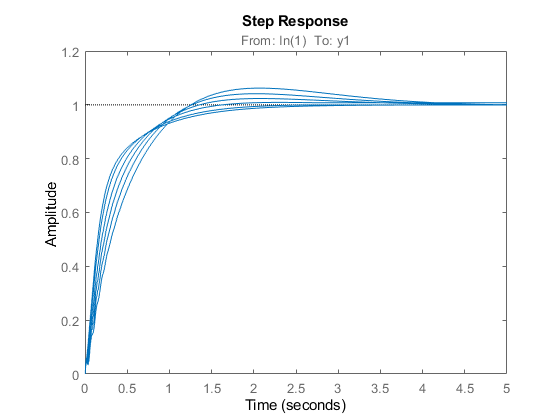

step(T_inf_2);

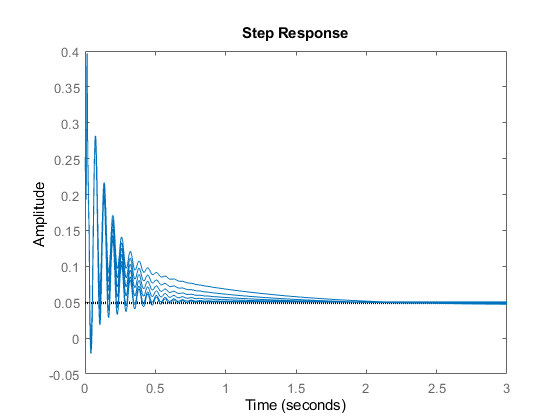

step(U_inf_2);

Reducing controller order

order(K_inf_2)

ans = 13

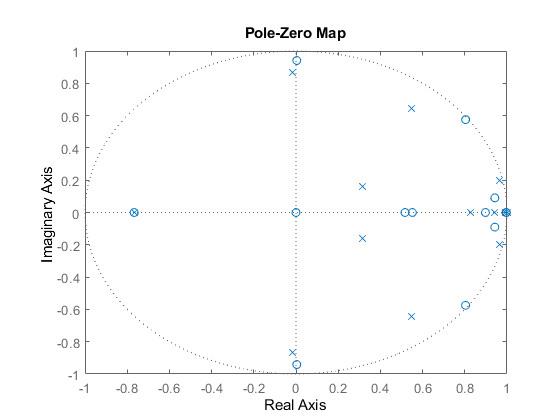

pzmap(K_inf_2);

[p,~]=pzmap(K_inf_2);


% Little function to test if the system is stable
if any(abs(p) >1)
    disp("The system is unstable")
else
    disp("The system is stable")
end

The system is stable


K_inf_r=minreal(K_inf_2,0.00002);

1 state removed.


order(K_inf_r)

ans = 12

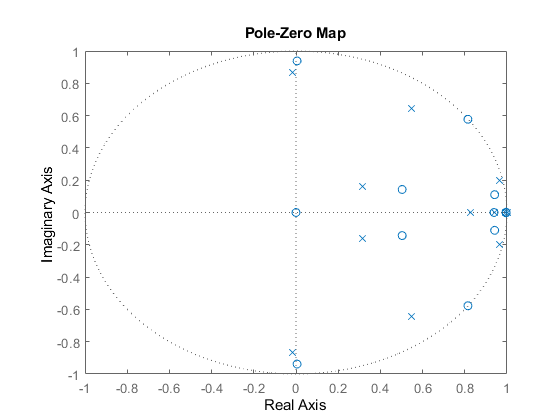


pzmap(K_inf_r)

[p,~]=pzmap(K_inf_r);

if any(abs(p) >1)
    disp("The system is unstable")
else
    disp("The system is stable")
end

The system is stable


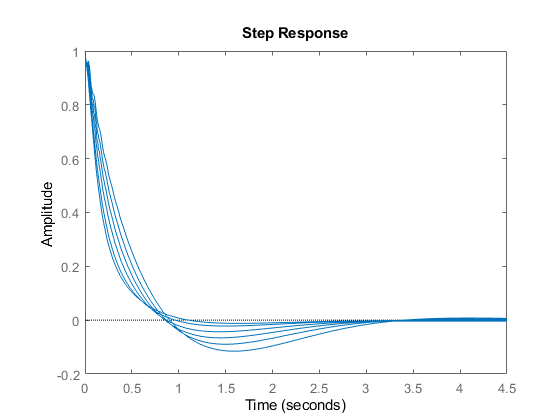

S = feedback( 1 , G * K_inf_r ) ;
T = feedback( G * K_inf_r , 1 ) ;
U = feedback( K_inf_r , G ) ;
figure(5)
step(S);

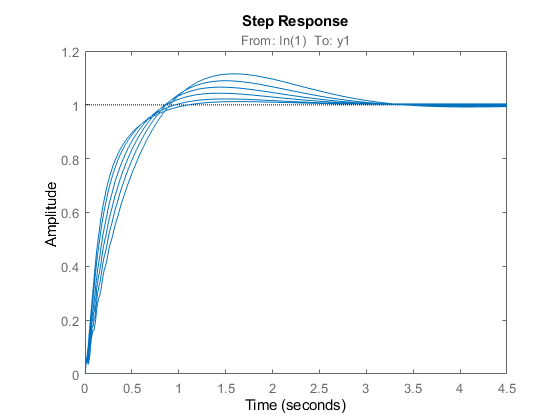

step(T);

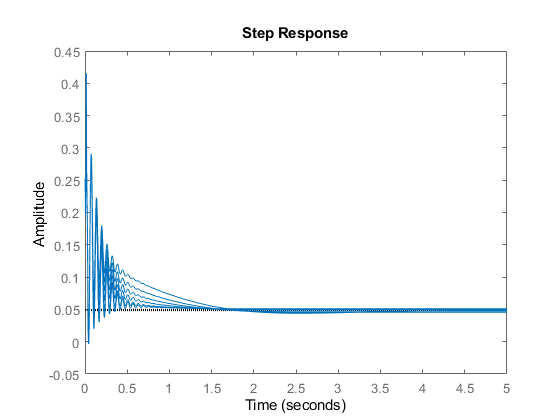

step(U);

The difference are very little compared to the full order controller.

Closed-loop norm

H_inf=[W1d*tf(S_inf_2) ; tf(W2n)*tf(T_inf_2)];
norm(H_inf,inf)

ans =     5.8138
    4.5500
    4.1937
    2.7838
    1.3053
    1.5688


Les 6 normes correspondent aux 6 systèmes. Le système étudié a la norme la plus faible

## H2 controller

Gnom_c=d2c(Gnom);

[A,B,C,D]=ssdata(Gnom_c);
n=size(A,2);
m=size(B,2);

Optimization problem :

L=sdpvar(n,n,'symmetric');
Y=sdpvar(m,n);
M=sdpvar(m,m);
lmi1=A*L + L*A' -B*Y - Y'*B' + B*B' <=0;
lmi2=[L Y';Y M] >=0;
lmi=[L>=0,lmi1,lmi2];
options=sdpsettings('solver','mosek');
optimize(lmi,trace(C*L*C')+trace(M),options);

MOSEK Version 10.1.28 (Build date: 2024-3-11 10:56:24)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 55              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 0               
  Matrix variables       : 3 (scalarized: 145)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - pri

L=value(L);
Y=value(Y);
M=value(M);
H2Norm=sqrt(trace(C*L*C')+trace(M))

H2Norm = 5.9733

K=Y/L

K =     2.2300    0.8070    3.5357    1.7117    3.8653    2.8378    2.2903    4.1913   15.8288


Step response

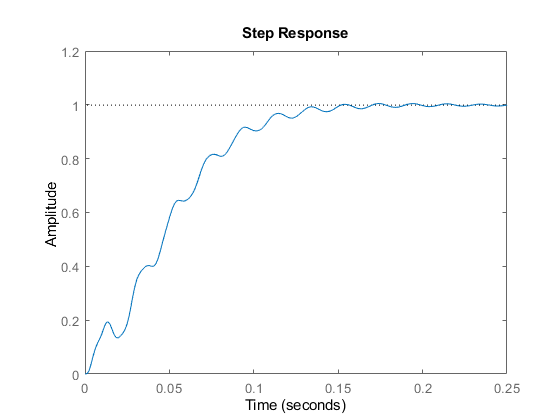

Gnom_closed=ss(A-B*K,B,C,D);
step(Gnom_closed)

Q=C'*C;
R=1;

K_lqr=lqr(A,B,Q,R)

K_lqr =     2.2300    0.8070    3.5357    1.7117    3.8653    2.8378    2.2903    4.1913   15.8288



diff=abs(norm(K,2)-norm(K_lqr,2))

diff = 1.0644e-05

Gnom_closed_lqr=ss(A-B*K_lqr,B,C,D);
step(Gnom_closed_lqr)

### Data-driven

%Stabilizing initial controller
z=tf("z");
c=0.0001;
Kc = c/(1-z^(-1))

Kc =
 
  0.0001 z
  --------
   z - 1
 
Sample time: unspecified
Discrete-time transfer function.



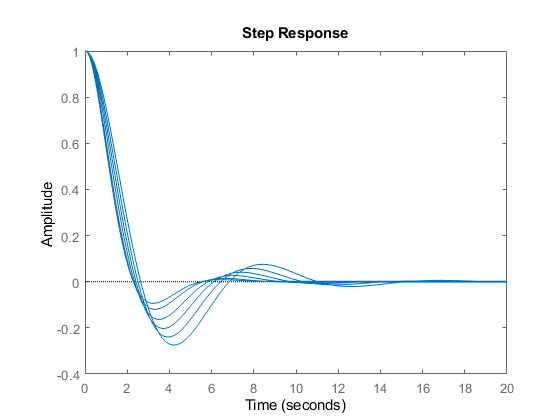


S = feedback( 1 , G * Kc ) ;
T = feedback( G * Kc , 1 ) ;
U = feedback( Kc , G ) ;
figure(6)
step(S);

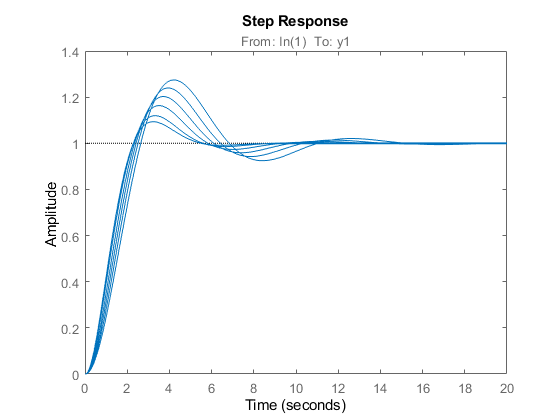

step(T);

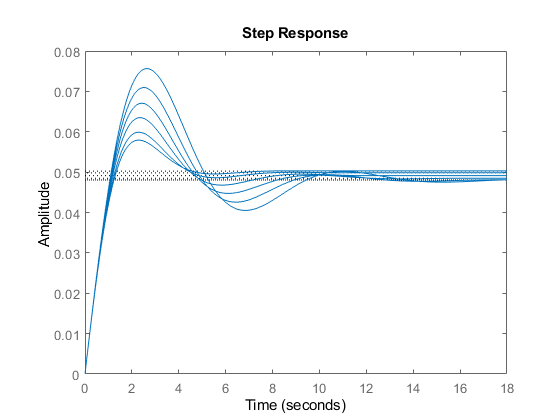

step(U);

Multiplicative uncertainty

We start by looking for a controller of the same order as the model based design

% Load empty structure
[SYS, OBJ, CON, PAR] = datadriven.utils.emptyStruct();

% ------------------------------------------------------------------------------
%   Initial controller
% ------------------------------------------------------------------------------
                   % Initial controller
[num, den] = tfdata(Kc, 'v');   % Extract numerator and denominator
order_cont=15;

den(order_cont + 1) = 0; % Zero padding to have same order as desired controller
num(order_cont + 1) = 0; % Zero padding to have same order as desired controller

% Fixed parts of the controller
%   NOTE: Initial controller should contain the fixed parts too!
Fy = 1;                 % Fixed part of denominator as polynomial
den = deconv(den, Fy);  % Remove fixed part of denominator

Fx = 1;                 % Fixed part of numerator as polynomial
num = deconv(num, Fx);  % Remove fixed part of numerator

SYS.controller.num = num;
SYS.controller.den = den;
SYS.controller.Ts = Ts;
SYS.controller.Fx = Fx;
SYS.controller.Fy = Fy;

% ------------------------------------------------------------------------------
%   Nominal system(s)
% ------------------------------------------------------------------------------
% Systems should be LTI systems (`ss`, `tf`, `frd`, ...)
SYS.model = tf(Gnom)

SYS = struct with fields:
         model: [1×1 tf]
             W: []
    controller: [1×1 struct]



% ------------------------------------------------------------------------------
%   Frequencies for controller synthesis
% ------------------------------------------------------------------------------
SYS.W = logspace(-2,log10(pi/Ts),400);

% ------------------------------------------------------------------------------
%   Filters for objectives
% ------------------------------------------------------------------------------
% Filter should be LTI systems (`ss`, `tf`, `frd`, ...)
% For unused objectives, set filters to []
OBJ.oinf.W1 = W1d;   % ║W1 S║∞
OBJ.oinf.W2 = tf(W2n);   % ║W2 T║∞
OBJ.oinf.W3 = tf(W3);   % ║W3 U║∞
OBJ.oinf.W4 = [];   % ║W4 V║∞

OBJ.o2.W1 = [];     % ║W1 S║₂
OBJ.o2.W2 = [];     % ║W2 T║₂
OBJ.o2.W3 = [];     % ║W3 U║₂
OBJ.o2.W4 = [];     % ║W4 V║₂

OBJ.LSinf.Ld = [];  % ║W (Ld - G K)║∞
OBJ.LSinf.W  = [];

OBJ.LS2.Ld = [];    % ║W (Ld - G K)║₂
OBJ.LS2.W  = [];

% ------------------------------------------------------------------------------
%   Filters for constraints
% ------------------------------------------------------------------------------
% Filter should be LTI systems (`ss`, `tf`, `frd`, ...)
% For unused constraints, set filters to []
CON.W1 = W1d;    % ║W1 S║∞ ≤ 1
CON.W2 = tf(W2n);    % ║W2 T║∞ ≤ 1
CON.W3 = tf(W3);    % ║W3 U║∞ ≤ 1
CON.W4 = [];    % ║W4 V║∞ ≤ 1

% ------------------------------------------------------------------------------
%   Optimisation parameters
% ------------------------------------------------------------------------------
PAR.tol = 1e-4;     % Numerical tolerance for convergence
PAR.maxIter = 100;  % Maximum number of allowed iterations

verbosity = true;   % To print controller synthesis iterations
solver = "mosek";        % Solver to use for optimisation ("mosek", "sedumi", ...)

% ------------------------------------------------------------------------------
%   Solve the datadriven controller synthesis problem
% ------------------------------------------------------------------------------
[K_mu_max_order, sol] = datadriven.datadriven(SYS, OBJ, CON, PAR, verbosity, solver);

INFO: Solving for optimal controller in datadriven framework...
  |------|------------|------------|-------------|------------|
  | Iter |   Slack    |  Objective |   Decrease  | Solve Time |
  |------|------------|------------|-------------|------------|
  |  001 | 1.9005e+00 |            |             |       0.36 |
  |  002 | 1.5694e+00 |            | -2.0458e+00 |       1.03 |
  |  003 | 1.5561e+00 |            | -2.2136e-01 |       1.42 |
  |  004 | 1.5353e+00 |            | -1.4995e-01 |       2.49 |
  |  005 | 1.5208e+00 |            | -1.3517e-01 |       2.91 |
  |  006 | 1.5042e+00 |            | -1.2733e-01 |       3.43 |
  |  007 | 1.4857e+00 |            | -1.2965e-01 |       4.09 |
  |  008 | 1.4655e+00 |            | -1.3530e-01 |       4.93 |
  |  009 | 1.4493e+00 |            | -1.3760e-01 |       5.54 |
  |  010 | 1.4433e+00 |            | -1.3280e-01 |       5.89 |
  |  011 | 1.4324e+00 |            | -1.3367e-01 |       6.11 |
  |  012 | 1.4320e+00 |            | -1.

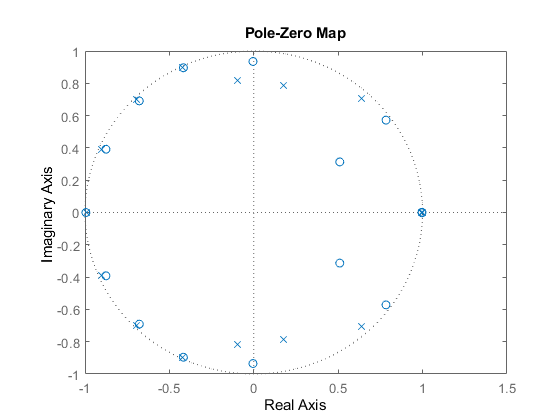

pzmap(K_mu_max_order);

[p,~]=pzmap(K_mu_max_order);

if any(abs(p) >1)
    disp("The system is unstable")
else
    disp("The system is stable")
end

The system is unstable


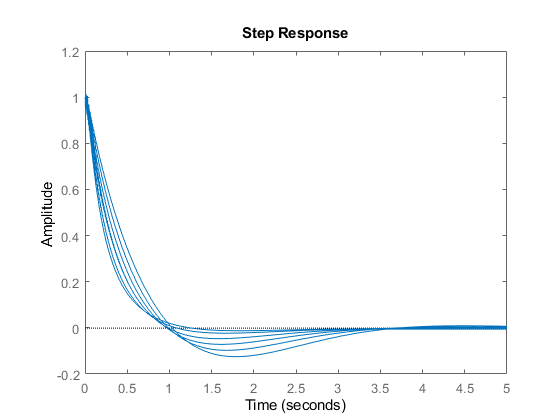


S = feedback( 1 , G * K_mu_max_order ) ;
T = feedback( G * K_mu_max_order , 1 ) ;
U = feedback( K_mu_max_order , G ) ;
figure(7)
step(S);

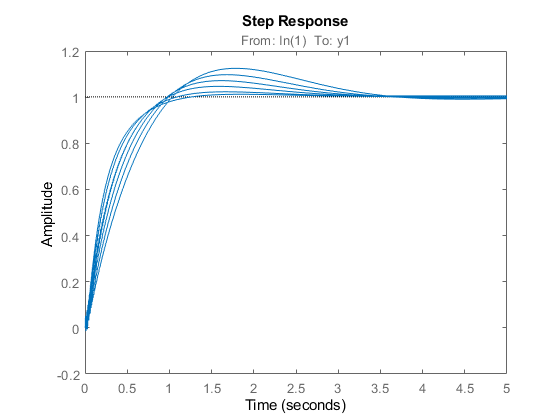

step(T);

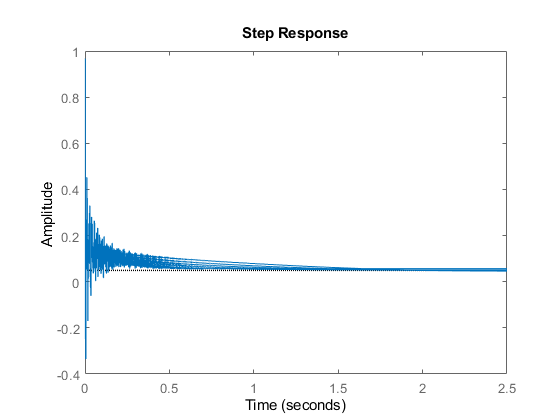

step(U);

Ajouter une partie avec la fonction stepinfo de matlab pour pouvoir comparer

With the data-driven method, we can look for controller of much lower orders. Let's look for a stabilizing controller of order 5 :

% Load empty structure
[SYS, OBJ, CON, PAR] = datadriven.utils.emptyStruct();

% ------------------------------------------------------------------------------
%   Initial controller
% ------------------------------------------------------------------------------
                   % Initial controller
[num, den] = tfdata(Kc, 'v');   % Extract numerator and denominator
order_cont=5;

den(order_cont + 1) = 0; % Zero padding to have same order as desired controller
num(order_cont + 1) = 0; % Zero padding to have same order as desired controller

% Fixed parts of the controller
%   NOTE: Initial controller should contain the fixed parts too!
Fy = 1;                 % Fixed part of denominator as polynomial
den = deconv(den, Fy);  % Remove fixed part of denominator

Fx = 1;                 % Fixed part of numerator as polynomial
num = deconv(num, Fx);  % Remove fixed part of numerator

SYS.controller.num = num;
SYS.controller.den = den;
SYS.controller.Ts = Ts;
SYS.controller.Fx = Fx;
SYS.controller.Fy = Fy;

% ------------------------------------------------------------------------------
%   Nominal system(s)
% ------------------------------------------------------------------------------
% Systems should be LTI systems (`ss`, `tf`, `frd`, ...)
SYS.model = tf(Gnom)

SYS = struct with fields:
         model: [1×1 tf]
             W: []
    controller: [1×1 struct]



% ------------------------------------------------------------------------------
%   Frequencies for controller synthesis
% ------------------------------------------------------------------------------
SYS.W = logspace(-2,log10(pi/Ts),400);

% ------------------------------------------------------------------------------
%   Filters for objectives
% ------------------------------------------------------------------------------
% Filter should be LTI systems (`ss`, `tf`, `frd`, ...)
% For unused objectives, set filters to []
OBJ.oinf.W1 = W1d;   % ║W1 S║∞
OBJ.oinf.W2 = tf(W2n);   % ║W2 T║∞
OBJ.oinf.W3 = tf(W3);   % ║W3 U║∞
OBJ.oinf.W4 = [];   % ║W4 V║∞

OBJ.o2.W1 = [];     % ║W1 S║₂
OBJ.o2.W2 = [];     % ║W2 T║₂
OBJ.o2.W3 = [];     % ║W3 U║₂
OBJ.o2.W4 = [];     % ║W4 V║₂

OBJ.LSinf.Ld = [];  % ║W (Ld - G K)║∞
OBJ.LSinf.W  = [];

OBJ.LS2.Ld = [];    % ║W (Ld - G K)║₂
OBJ.LS2.W  = [];

% ------------------------------------------------------------------------------
%   Filters for constraints
% ------------------------------------------------------------------------------
% Filter should be LTI systems (`ss`, `tf`, `frd`, ...)
% For unused constraints, set filters to []
CON.W1 = W1d;    % ║W1 S║∞ ≤ 1
CON.W2 = tf(W2n);    % ║W2 T║∞ ≤ 1
CON.W3 = tf(W3);    % ║W3 U║∞ ≤ 1
CON.W4 = [];    % ║W4 V║∞ ≤ 1

% ------------------------------------------------------------------------------
%   Optimisation parameters
% ------------------------------------------------------------------------------
PAR.tol = 1e-4;     % Numerical tolerance for convergence
PAR.maxIter = 100;  % Maximum number of allowed iterations

verbosity = true;   % To print controller synthesis iterations
solver = "mosek";        % Solver to use for optimisation ("mosek", "sedumi", ...)

% ------------------------------------------------------------------------------
%   Solve the datadriven controller synthesis problem
% ------------------------------------------------------------------------------
[K_mu_r_order, sol] = datadriven.datadriven(SYS, OBJ, CON, PAR, verbosity, solver);

INFO: Solving for optimal controller in datadriven framework...
  |------|------------|------------|-------------|------------|
  | Iter |   Slack    |  Objective |   Decrease  | Solve Time |
  |------|------------|------------|-------------|------------|
  |  001 | 2.5168e+00 |            |             |       0.22 |
  |  002 | 1.6452e+00 |            | -2.9251e+00 |       0.65 |
  |  003 | 1.7182e+00 |            | -3.7555e-01 |       0.80 |
  |  004 | 1.7660e+00 |            | -4.4949e-02 |       1.12 |
  |  005 | 1.7546e+00 |            | -1.3435e-02 |       1.36 |
  |  006 | 1.7449e+00 |            | -9.7303e-03 |       1.55 |
  |  007 | 1.7369e+00 |            | -8.0030e-03 |       1.77 |
  |  008 | 1.7302e+00 |            | -6.6860e-03 |       1.95 |
  |  009 | 1.7245e+00 |            | -5.6607e-03 |       2.21 |
  |  010 | 1.7194e+00 |            | -5.1123e-03 |       2.43 |
  |  011 | 1.7150e+00 |            | -4.4041e-03 |       2.63 |
  |  012 | 1.7111e+00 |            | -3.

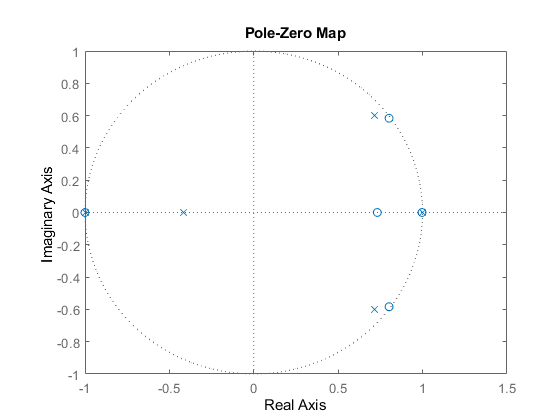

pzmap(K_mu_r_order);

[p,~]=pzmap(K_mu_r_order);

if any(abs(p) >1)
    disp("The system is unstable")
else
    disp("The system is stable")
end

The system is unstable


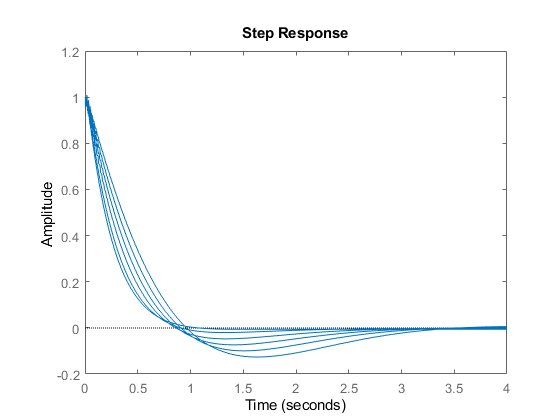


S = feedback( 1 , G * K_mu_r_order ) ;
T = feedback( G * K_mu_r_order , 1 ) ;
U = feedback( K_mu_r_order , G ) ;
figure(8)
step(S);

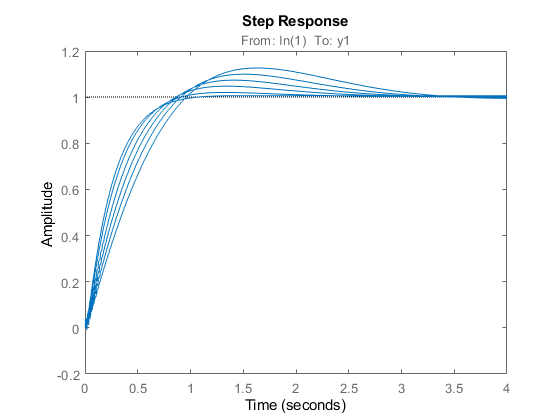

step(T);

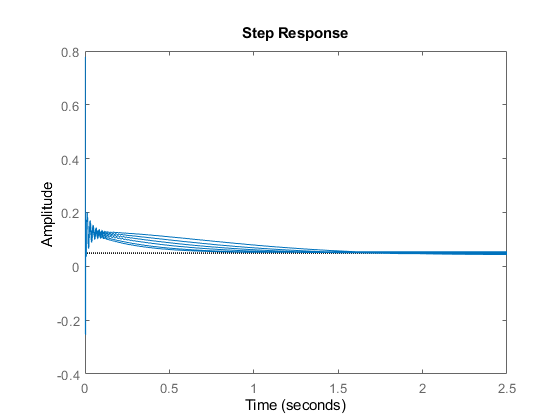

step(U);

The system is stable. Comparer les performances

Multimodel uncertainty

% Load empty structure
[SYS, OBJ, CON, PAR] = datadriven.utils.emptyStruct();

% ------------------------------------------------------------------------------
%   Initial controller
% ------------------------------------------------------------------------------
                   % Initial controller
[num, den] = tfdata(Kc, 'v');   % Extract numerator and denominator
order_cont=13;

den(order_cont + 1) = 0; % Zero padding to have same order as desired controller
num(order_cont + 1) = 0; % Zero padding to have same order as desired controller

% Fixed parts of the controller
%   NOTE: Initial controller should contain the fixed parts too!
Fy = 1;                 % Fixed part of denominator as polynomial
den = deconv(den, Fy);  % Remove fixed part of denominator

Fx = 1;                 % Fixed part of numerator as polynomial
num = deconv(num, Fx);  % Remove fixed part of numerator

SYS.controller.num = num;
SYS.controller.den = den;
SYS.controller.Ts = Ts;
SYS.controller.Fx = Fx;
SYS.controller.Fy = Fy;

% ------------------------------------------------------------------------------
%   Nominal system(s)
% ------------------------------------------------------------------------------
% Systems should be LTI systems (`ss`, `tf`, `frd`, ...)
SYS.model = tf(G)

SYS = struct with fields:
         model: [1×1×6×1 tf]
             W: []
    controller: [1×1 struct]



% ------------------------------------------------------------------------------
%   Frequencies for controller synthesis
% ------------------------------------------------------------------------------
SYS.W = logspace(-2,log10(pi/Ts),400);

% ------------------------------------------------------------------------------
%   Filters for objectives
% ------------------------------------------------------------------------------
% Filter should be LTI systems (`ss`, `tf`, `frd`, ...)
% For unused objectives, set filters to []
OBJ.oinf.W1 = W1d;   % ║W1 S║∞
OBJ.oinf.W2 = tf(W2n);   % ║W2 T║∞
OBJ.oinf.W3 = tf(W3);   % ║W3 U║∞
OBJ.oinf.W4 = [];   % ║W4 V║∞

OBJ.o2.W1 = [];     % ║W1 S║₂
OBJ.o2.W2 = [];     % ║W2 T║₂
OBJ.o2.W3 = [];     % ║W3 U║₂
OBJ.o2.W4 = [];     % ║W4 V║₂

OBJ.LSinf.Ld = [];  % ║W (Ld - G K)║∞
OBJ.LSinf.W  = [];

OBJ.LS2.Ld = [];    % ║W (Ld - G K)║₂
OBJ.LS2.W  = [];

% ------------------------------------------------------------------------------
%   Filters for constraints
% ------------------------------------------------------------------------------
% Filter should be LTI systems (`ss`, `tf`, `frd`, ...)
% For unused constraints, set filters to []
CON.W1 = W1d;    % ║W1 S║∞ ≤ 1
CON.W2 = tf(W2n);    % ║W2 T║∞ ≤ 1
CON.W3 = tf(W3);    % ║W3 U║∞ ≤ 1
CON.W4 = [];    % ║W4 V║∞ ≤ 1

% ------------------------------------------------------------------------------
%   Optimisation parameters
% ------------------------------------------------------------------------------
PAR.tol = 1e-4;     % Numerical tolerance for convergence
PAR.maxIter = 50;  % Maximum number of allowed iterations

verbosity = true;   % To print controller synthesis iterations
solver = "mosek";        % Solver to use for optimisation ("mosek", "sedumi", ...)

% ------------------------------------------------------------------------------
%   Solve the datadriven controller synthesis problem
% ------------------------------------------------------------------------------
[K_mm_max_order, sol] = datadriven.datadriven(SYS, OBJ, CON, PAR, verbosity, solver);

INFO: Solving for optimal controller in datadriven framework...
  |------|------------|------------|-------------|------------|
  | Iter |   Slack    |  Objective |   Decrease  | Solve Time |
  |------|------------|------------|-------------|------------|
  |  001 | 4.3367e+00 |            |             |       1.72 |
  |  002 | 2.1289e+00 |            | -5.0440e+00 |       5.58 |
  |  003 | 2.1680e+00 |            | -1.1694e+00 |       9.34 |
  |  004 | 2.1593e+00 |            | -1.0593e+00 |      16.03 |
  |  005 | 2.1586e+00 |            | -1.0566e+00 |      18.30 |
  |  006 | 2.1573e+00 |            | -1.0565e+00 |      21.86 |
  |  007 | 2.1566e+00 |            | -1.0565e+00 |      28.53 |
  |  008 | 2.1565e+00 |            | -1.0560e+00 |      31.99 |
  |  009 | 2.1553e+00 |            | -1.0568e+00 |      37.37 |
  |  010 | 2.1546e+00 |            | -1.0572e+00 |      50.87 |
  |  011 | 2.1543e+00 |            | -1.0572e+00 |      52.88 |
  |  012 | 2.1540e+00 |            | -1.

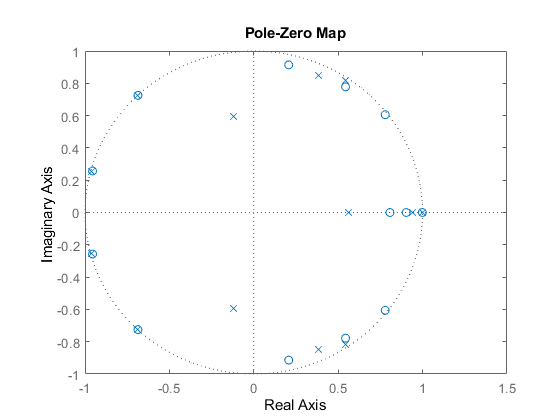

pzmap(K_mm_max_order);

[p,~]=pzmap(K_mm_max_order);

if any(abs(p) >1)
    disp("The system is unstable")
else
    disp("The system is stable")
end

The system is unstable


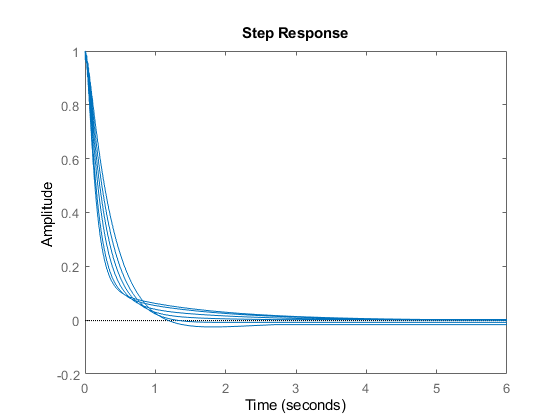


S = feedback( 1 , G * K_mm_max_order ) ;
T = feedback( G * K_mm_max_order , 1 ) ;
U = feedback( K_mm_max_order , G ) ;
figure(9)
step(S);

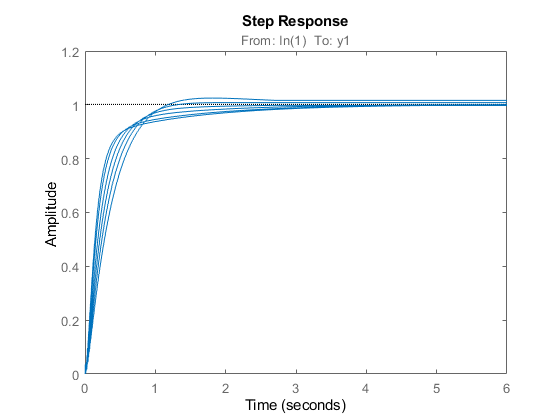

step(T);

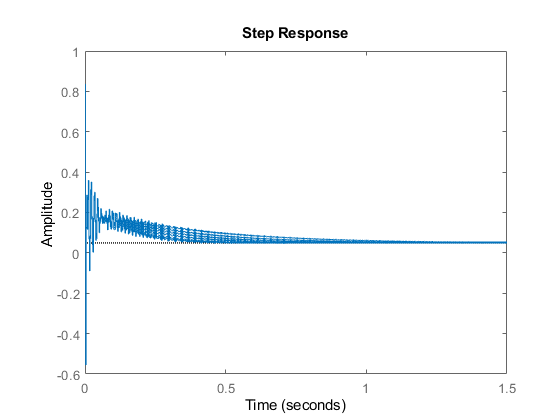

step(U);

Better performances + add comparison

% Load empty structure
[SYS, OBJ, CON, PAR] = datadriven.utils.emptyStruct();

% ------------------------------------------------------------------------------
%   Initial controller
% ------------------------------------------------------------------------------
                   % Initial controller
[num, den] = tfdata(Kc, 'v');   % Extract numerator and denominator
order_cont=5;

den(order_cont + 1) = 0; % Zero padding to have same order as desired controller
num(order_cont + 1) = 0; % Zero padding to have same order as desired controller

% Fixed parts of the controller
%   NOTE: Initial controller should contain the fixed parts too!
Fy = 1;                 % Fixed part of denominator as polynomial
den = deconv(den, Fy);  % Remove fixed part of denominator

Fx = 1;                 % Fixed part of numerator as polynomial
num = deconv(num, Fx);  % Remove fixed part of numerator

SYS.controller.num = num;
SYS.controller.den = den;
SYS.controller.Ts = Ts;
SYS.controller.Fx = Fx;
SYS.controller.Fy = Fy;

% ------------------------------------------------------------------------------
%   Nominal system(s)
% ------------------------------------------------------------------------------
% Systems should be LTI systems (`ss`, `tf`, `frd`, ...)
SYS.model = tf(G)

SYS = struct with fields:
         model: [1×1×6×1 tf]
             W: []
    controller: [1×1 struct]



% ------------------------------------------------------------------------------
%   Frequencies for controller synthesis
% ------------------------------------------------------------------------------
SYS.W = logspace(-2,log10(pi/Ts),400);

% ------------------------------------------------------------------------------
%   Filters for objectives
% ------------------------------------------------------------------------------
% Filter should be LTI systems (`ss`, `tf`, `frd`, ...)
% For unused objectives, set filters to []
OBJ.oinf.W1 = W1d;   % ║W1 S║∞
OBJ.oinf.W2 = tf(W2n);   % ║W2 T║∞
OBJ.oinf.W3 = tf(W3);   % ║W3 U║∞
OBJ.oinf.W4 = [];   % ║W4 V║∞

OBJ.o2.W1 = [];     % ║W1 S║₂
OBJ.o2.W2 = [];     % ║W2 T║₂
OBJ.o2.W3 = [];     % ║W3 U║₂
OBJ.o2.W4 = [];     % ║W4 V║₂

OBJ.LSinf.Ld = [];  % ║W (Ld - G K)║∞
OBJ.LSinf.W  = [];

OBJ.LS2.Ld = [];    % ║W (Ld - G K)║₂
OBJ.LS2.W  = [];

% ------------------------------------------------------------------------------
%   Filters for constraints
% ------------------------------------------------------------------------------
% Filter should be LTI systems (`ss`, `tf`, `frd`, ...)
% For unused constraints, set filters to []
CON.W1 = W1d;    % ║W1 S║∞ ≤ 1
CON.W2 = tf(W2n);    % ║W2 T║∞ ≤ 1
CON.W3 = tf(W3);    % ║W3 U║∞ ≤ 1
CON.W4 = [];    % ║W4 V║∞ ≤ 1

% ------------------------------------------------------------------------------
%   Optimisation parameters
% ------------------------------------------------------------------------------
PAR.tol = 1e-4;     % Numerical tolerance for convergence
PAR.maxIter = 50;  % Maximum number of allowed iterations

verbosity = true;   % To print controller synthesis iterations
solver = "mosek";        % Solver to use for optimisation ("mosek", "sedumi", ...)

% ------------------------------------------------------------------------------
%   Solve the datadriven controller synthesis problem
% ------------------------------------------------------------------------------
[K_mm_r_order, sol] = datadriven.datadriven(SYS, OBJ, CON, PAR, verbosity, solver);

INFO: Solving for optimal controller in datadriven framework...
  |------|------------|------------|-------------|------------|
  | Iter |   Slack    |  Objective |   Decrease  | Solve Time |
  |------|------------|------------|-------------|------------|
  |  001 | 5.7928e+00 |            |             |       1.23 |
  |  002 | 1.9691e+00 |            | -6.5831e+00 |       2.31 |
  |  003 | 1.9125e+00 |            | -1.7876e+00 |       3.39 |
  |  004 | 1.9839e+00 |            | -1.4060e+00 |       4.75 |
  |  005 | 1.9954e+00 |            | -1.3644e+00 |       6.09 |
  |  006 | 2.0054e+00 |            | -1.3458e+00 |       7.38 |
  |  007 | 2.0175e+00 |            | -1.3299e+00 |       9.85 |
  |  008 | 2.0201e+00 |            | -1.3222e+00 |      10.64 |
  |  009 | 2.0205e+00 |            | -1.3193e+00 |      11.40 |
  |  010 | 2.0209e+00 |            | -1.3165e+00 |      12.25 |
  |  011 | 2.0213e+00 |            | -1.3140e+00 |      12.98 |
  |  012 | 2.0217e+00 |            | -1.

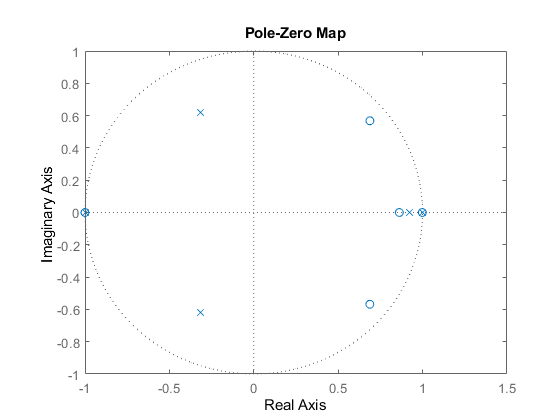

pzmap(K_mm_r_order);

[p,~]=pzmap(K_mm_r_order);

if any(abs(p) >1)
    disp("The system is unstable")
else
    disp("The system is stable")
end

The system is unstable


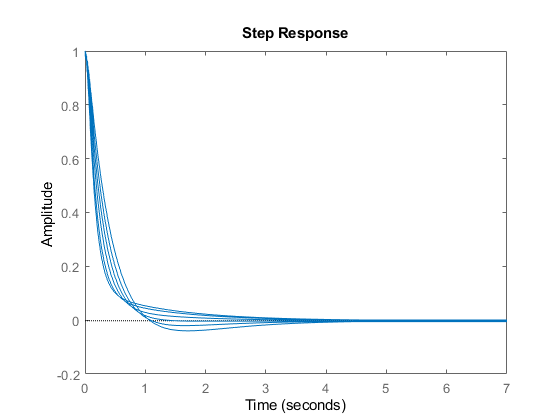


S = feedback( 1 , G * K_mm_r_order ) ;
T = feedback( G * K_mm_r_order , 1 ) ;
U = feedback( K_mm_r_order , G ) ;
figure(10)
step(S);

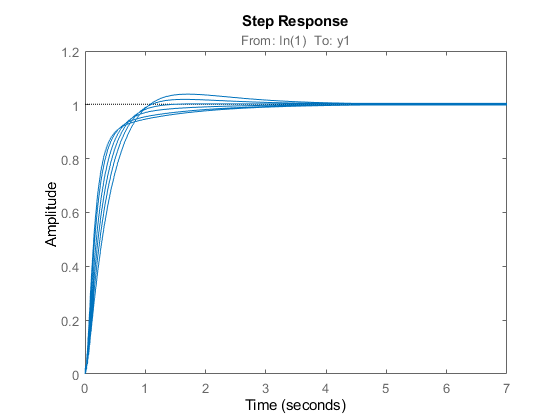

step(T);

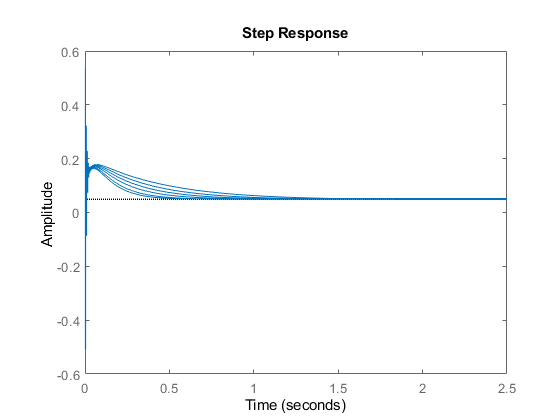

step(U);

Comparison data-driven approach - model-based approach. Data-driven is quite long to compute.